clear; close all; clc

## Experiment 1 - Bepaling l

syms g l theta(t) omega(t)

eqs = [diff(theta,t) == omega;
       diff(omega,t) == (3/4)*(g/l)*theta];

sol = dsolve(eqs,[theta(0)==0.01, omega(0)==0]);
theta = simplify(sol.theta)

$$theta = \frac{\cosh\left(\frac{\sqrt{3}\,\sqrt{g}\,t}{2\,\sqrt{l}}\right)}{100}$$

g_n = 9.81;
t = 0:0.05:(400-1)*0.05;
phi_max = pi/2.1;

data = readmatrix('pendulum_states_exp1.csv');    theta_sim = data(:,3);
% data = readmatrix('pendulum_measurements_exp1.csv');    theta_sim = data(:,2);
l_opt = fminsearch(@(l) theta_mse(l,t,matlabFunction(theta),theta_sim, g_n, phi_max), 0.10);
disp("Optimale lengte l = " + l_opt)

Optimale lengte l = 0.12164


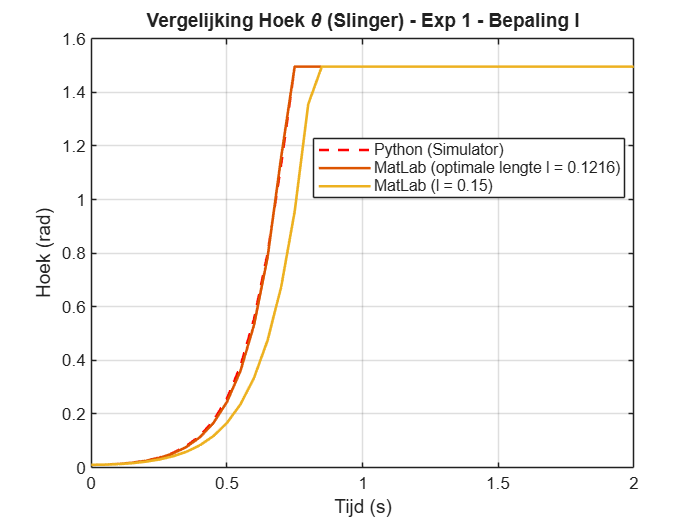

theta_fun_opt = matlabFunction(subs(theta,[g,l],[g_n,l_opt]));
theta_model_opt = theta_fun_opt(t);

theta_fun_015 = matlabFunction(subs(theta,[g,l],[g_n,0.15]));
theta_model_015 = theta_fun_015(t);

theta_model_opt = min(theta_model_opt,phi_max);
theta_model_015 = min(theta_model_015,phi_max);

figure
plot(t,theta_sim,'r--','LineWidth',1.5); hold on
plot(t,theta_model_opt,'LineWidth',1.5)
plot(t,theta_model_015,'LineWidth',1.5)
xlabel('Tijd (s)')
xlim([0,2]);
ylim([0,1.6]);
ylabel('Hoek (rad)')
title('Vergelijking Hoek \theta (Slinger) - Exp 1 - Bepaling l')
legend('Python (Simulator)',sprintf('MatLab (optimale lengte l = %0.4f)',l_opt), 'MatLab (l = 0.15)','Location','best')
grid on

## Experiment 1bis - Bepaling l

% data = readmatrix('pendulum_measurements_exp1bis.csv');
% theta_sim = data(:,2);
% theta_sim(theta_sim < 0) = theta_sim(theta_sim < 0) + 2*pi;
% 
% [pks, locs] = findpeaks(theta_sim, t)
% periods = diff(locs)
% T = mean(periods)
% l = (T/(pi))^2*3*g_n/16
% figure
% plot(t,theta_sim,'r--','LineWidth',1.5); hold on
% xlabel('Tijd (s)')
% xlim([0,10]);
% ylabel('Hoek (rad)')
% title('Vergelijking Hoek \theta (Slinger) - Exp 1bis - Bepaling l')
% legend('Python (Simulator)')%,'MatLab (optimale lengte l = 0.12152)', 'MatLab (l = 0.15)','Location','best')
% grid on

## Experiment 2 - Bepaling b en M+m

syms Mplusm b F v(t) x(t) t

eqn = [diff(x) == v,(Mplusm)*diff(v) + b*v == F]

$$eqn(t) = \left(\begin{array}{cc} \frac{\partial }{\partial t}x\left(t\right)=v\left(t\right) & \mathrm{Mplusm}\,\frac{\partial }{\partial t}v\left(t\right)+b\,v\left(t\right)=F \end{array}\right)$$

sol = dsolve(eqn,[x(0)==0, v(0)==0]);
x = simplify(sym(sol.x))

$$x = \frac{F\,\mathrm{Mplusm}\,{\mathrm{e}}^{-\frac{b\,t}{\mathrm{Mplusm}}}-F\,\mathrm{Mplusm}+F\,b\,t}{b^{2}}$$

x_fun = matlabFunction(sol.x, 'Vars', {t, Mplusm, b, F})

x_fun = function_handle with value:
    @(t,Mplusm,b,F)(F.*t)./b+(Mplusm.*exp(-(b.*t)./Mplusm).*(F./b-(F.*exp((b.*t)./Mplusm))./b))./b


t = 0:0.05:(400-1)*0.05;
x_max = 0.9;
F = 0.01;

data = readmatrix('pendulum_states_exp2bisbis.csv');
 % data = readmatrix('pendulum_measurements_exp2bisbis.csv');

x_sim = data(:,1);
x_sim = min(x_sim,x_max);

params0 = [1.78, 0.178];  % startwaarden
params_opt = fminsearch(@(p) x_mse(p, t, x_fun, x_sim, x_max, F), params0);

M_plus_m_opt = params_opt(1);
b_opt = params_opt(2);

disp(['Optimale M+m = ', num2str(M_plus_m_opt), ', b = ', num2str(b_opt)])

Optimale M+m = 0.69997, b = 0.10001


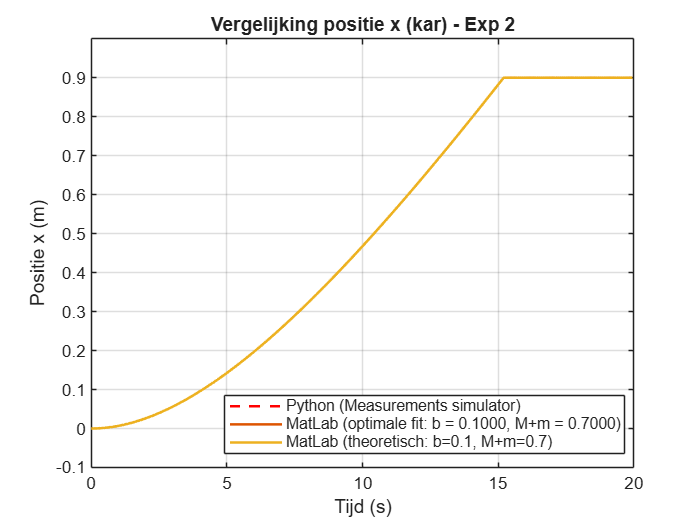

x_model_opt = x_fun(t,M_plus_m_opt,b_opt,F);
x_model_theory = x_fun(t,0.7,0.1,F);  % puur theoretisch

x_model_opt = min(x_model_opt,x_max);
x_model_theory = min(x_model_theory,x_max);

figure
plot(t,x_sim,'r--','LineWidth',1.5); hold on
plot(t,x_model_opt,'LineWidth',1.5)
plot(t,x_model_theory,'LineWidth',1.5)
xlabel('Tijd (s)')
ylabel('Positie x (m)')
xlim([0,20]); ylim([-0.1 1]);
title('Vergelijking positie x (kar) - Exp 2')
legend(sprintf('Python (Measurements simulator)'),sprintf('MatLab (optimale fit: b = %0.4f, M+m = %0.4f)',b_opt, M_plus_m_opt),sprintf('MatLab (theoretisch: b=0.1, M+m=0.7)'),'Location','best')
grid on

## Experiment 3 - Bepaling m en M

% m = 0.2, M = 0.5
syms m M
% l_opt = 0.15

data = readmatrix('pendulum_states_exp1.csv');    
x_sim = data(:,1);
theta_sim = data(:,3);

#### Puur massacentrum begintoestand = eindtoestand

x_kar_0 = x_sim(1);
[x_kar_1, idx] = max(x_sim)

x_kar_1 = 0.0413

idx = 16

t(idx)

ans = 0.7500

theta_0_pend = theta_sim(1);
theta_1_pend = theta_sim(idx);
x_pend_0 = x_kar_0 - l_opt*sin(theta_0_pend);
x_pend_1 = x_kar_1 - l_opt*sin(theta_1_pend);
x_center_mass_0 = (m*x_pend_0 + M*x_kar_0)/(m+M);
x_center_mass_1 = (m*x_pend_1 + M*x_kar_1)/(m+M);
eqns = [x_center_mass_0 == x_center_mass_1, M+m == M_plus_m_opt];
[M m] = solve(eqns, [M m]);
disp(vpa(M,4))

$$0.459$$

disp(vpa(m,4))

$$0.2409$$

#### Least mean square error op de volledige dataset -> beter

% l_opt = 0.15
x_sim = x_sim(1:16);      % Positie kar
theta_sim = theta_sim(1:16); % Hoek pendulum (rad)

% 2. Optimizatie: Zoek de 'm' die het zwaartepunt het meest constant houdt
% We weten dat M + m = M_plus_m_opt (uit vorig experiment)
m_start = 0.3; 
m_opt = fminsearch(@(m) massacentrum_mse(m, x_sim, theta_sim, l_opt, M_plus_m_opt), m_start);
M_opt = M_plus_m_opt - m_opt;

fprintf('Optimale resultaten Exp 3:\n');

Optimale resultaten Exp 3:


fprintf('Massa Pendulum (m): %.4f kg\n', m_opt);

Massa Pendulum (m): 0.2413 kg


fprintf('Massa Kar (M): %.4f kg\n', M_opt);

Massa Kar (M): 0.4586 kg


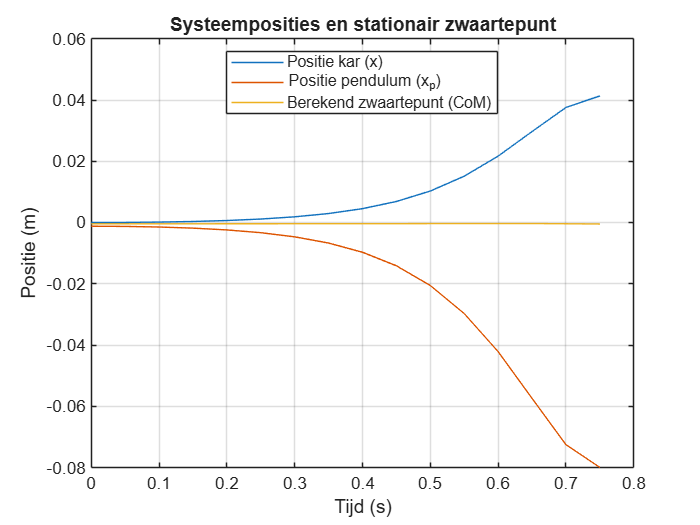

x_pend_sim = x_sim - l_opt * sin(theta_sim);
x_com_opt = (m_opt * x_pend_sim + M_opt * x_sim) / M_plus_m_opt;

figure;
plot(t(1:16), x_sim, 'DisplayName', 'Positie kar (x)'); hold on;
plot(t(1:16), x_pend_sim, 'DisplayName', 'Positie pendulum (x_p)');
plot(t(1:16), x_com_opt, 'DisplayName', 'Berekend zwaartepunt (CoM)');
title('Systeemposities en stationair zwaartepunt');
xlabel('Tijd (s)'); ylabel('Positie (m)');
legend('show','Location','best'); grid on;

## Conclusie

fprintf('Optimale resultaten:\n'); fprintf('Massa Pendulum (m): %.4f kg\n', m_opt); fprintf('Massa Kar (M): %.4f kg\n', M_opt); fprintf('Halflengte pendulum (l): %.4f m\n', l_opt'); fprintf('Wrijvingscoëfficïent (b): %.4f Ns/m\n', b_opt')

Optimale resultaten:
Massa Pendulum (m): 0.2413 kg
Massa Kar (M): 0.4586 kg
Halflengte pendulum (l): 0.1216 m
Wrijvingscoëfficïent (b): 0.1000 Ns/m


% clc; clear; close all

syms x(t) theta(t) F
syms M m g l b I
assume([g l m M b] > 0)


P = (M+m)*I + M*m*l^2

$$P = M\,m\,l^{2}+\text{I}\,\left(M+m\right)$$

eqn1 = (M+m)*diff(x,t) - m*l*cos(theta)*diff(theta,2) + m*l*sin(theta)*(diff(theta))^2 == F-diff(x)*b

$$eqn1(t) = -l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+l\,m\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+\left(M+m\right)\,\frac{\partial }{\partial t}x\left(t\right)=F-b\,\frac{\partial }{\partial t}x\left(t\right)$$

eqn2 = m*diff(x,2)*l*cos(theta) - m*l^2 * diff(theta,2) + m*g*l*sin(theta) == I * diff(theta,2)

$$eqn2(t) = -m\,l^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+m\,\cos\left(\theta \left(t\right)\right)\,l\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+g\,m\,\sin\left(\theta \left(t\right)\right)\,l=\text{I}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)$$

% solve([eqn1 eqn2],[x(t) theta(t)])


#### I_opt vergelijking met MathWorks help center:

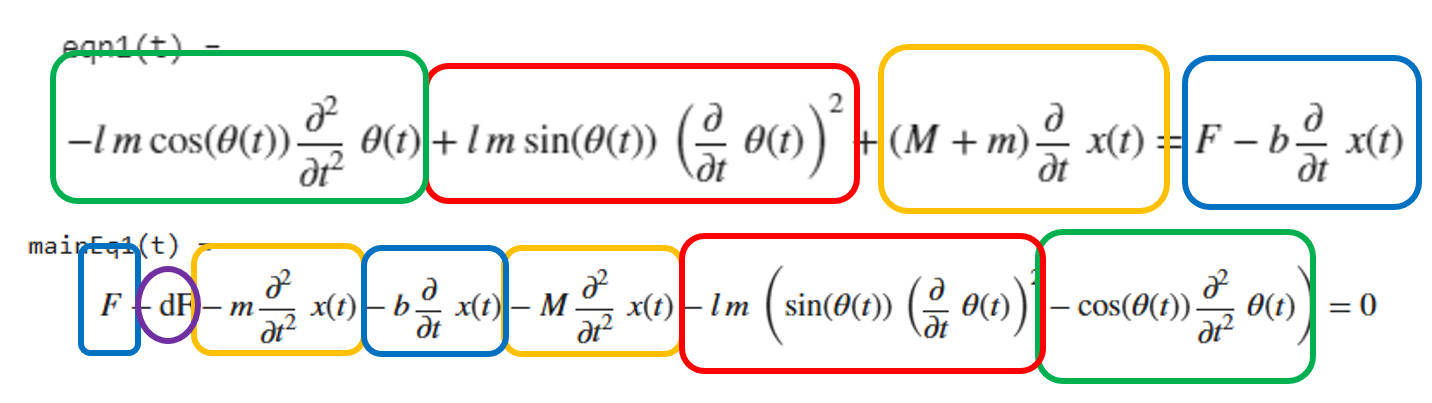

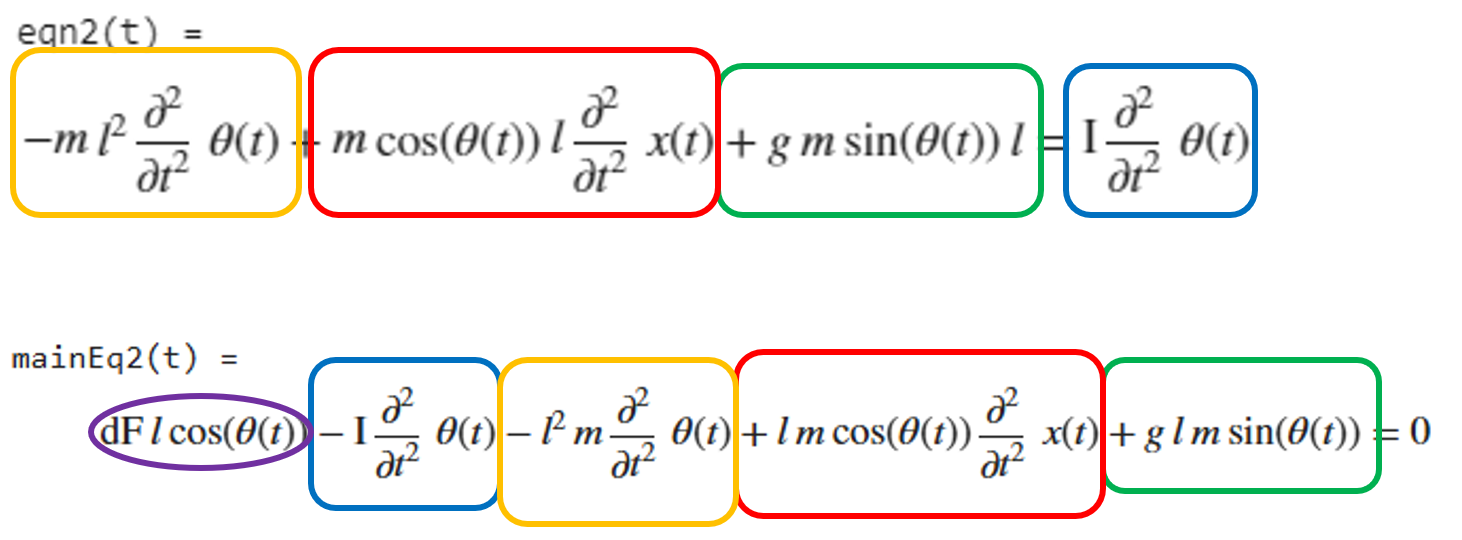

I_opt de afbeeldingen zijn de bovenste regels onze vgl'en, onderste die van MathWorks. Komen exact overeen op een dF term na. TBD wa da juist wilt zeggen. Gemini zegt:

"**Wat betreft de $dF$ term bij MathWorks: **Dat is de afgeleide van de kracht. I_opt de meeste mechanische systemen is de kracht een directe input ($u$), geen toestand waarvan de afgeleide ertoe doet. Omdat jouw vergelijking $F$ aan de rechterkant heeft staan als een "stap" of "impuls", kun je die $dF$ negeren voor je State-Space model."

[ssEqs,states] = odeToVectorField([eqn1 eqn2]);
simplify(ssEqs)

$$ans = \left(\begin{array}{c} Y_{2}\\ \frac{l\,m\,\sin\left(Y_{1}\right)\,{Y_{2}}^{2}-F+M\,Y_{4}+b\,Y_{4}+m\,Y_{4}}{l\,m\,\cos\left(Y_{1}\right)}\\ Y_{4}\\ \frac{\text{I}\,M\,Y_{4}-F\,\text{I}+l^{2}\,m^{2}\,Y_{4}+\text{I}\,b\,Y_{4}+\text{I}\,m\,Y_{4}-F\,l^{2}\,m+l^{3}\,m^{2}\,\sin\left(Y_{1}\right)\,{Y_{2}}^{2}+M\,l^{2}\,m\,Y_{4}+b\,l^{2}\,m\,Y_{4}-\frac{g\,l^{2}\,m^{2}\,\sin\left(2\,Y_{1}\right)}{2}+\text{I}\,l\,m\,\sin\left(Y_{1}\right)\,{Y_{2}}^{2}}{l^{2}\,m^{2}\,{\cos\left(Y_{1}\right)}^{2}} \end{array}\right)$$

A = [0 1 0 0; 0 (-b*(I+m*l^2))/P (m^2*l^2*g)/P 0; 0 0 0 1; 0 (-b*m*l)/P, m*g*l*(m+M)/P 0]

$$A = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -\frac{b\,\left(m\,l^{2}+\text{I}\right)}{\sigma_{1}} & \frac{g\,l^{2}\,m^{2}}{\sigma_{1}} & 0\\ 0 & 0 & 0 & 1\\ 0 & -\frac{b\,l\,m}{\sigma_{1}} & \frac{g\,l\,m\,\left(M+m\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=M\,m\,l^{2}+\text{I}\,\left(M+m\right) \end{array}$$

B = [0 (I + m*l^2)/P 0 (m*l)/P]

$$B = \left(\begin{array}{cccc} 0 & \frac{m\,l^{2}+\text{I}}{M\,m\,l^{2}+\text{I}\,\left(M+m\right)} & 0 & \frac{l\,m}{M\,m\,l^{2}+\text{I}\,\left(M+m\right)} \end{array}\right)$$

C = [1 0 0 0; 0 0 1 0];
D = 0;

gn = 9.81

gn = 9.8100


I_opt = 1/12 * m_opt * (2*l_opt)^2;
vpa(I_opt)

$$ans = 0.0011903621710538869141876583412909$$


P_opt = (M_opt+m_opt)*I_opt + M_opt*m_opt*l_opt^2;

P_opt = 0.0025

vpa(P_opt)

$$ans = 0.0024710024054160600187612928380076$$


%(m_opt*l_opt)/(M_opt*m_opt*l_opt^2 + I_opt*(M_opt + m_opt))

An = eval(subs(A,[M m g l b I],[M_opt m_opt gn l_opt b_opt I_opt]));

Bn = eval(subs(B,[M m g l b I],[M_opt m_opt gn l_opt b_opt I_opt]))';

Cn = eval(subs(C,[M m g l b I],[M_opt m_opt gn l_opt b_opt I_opt]));

Dn = eval(subs(D,[M m g l b I],[M_opt m_opt gn l_opt b_opt I_opt]));

sys = ss(An,Bn,Cn,Dn,'InputName',{'F'},'OutputName',{'x','\theta'})


sys =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0  -0.1927    3.422        0
   x3        0        0        0        1
   x4        0   -1.188    81.58        0
 
  B = 
           F
   x1      0
   x2  1.927
   x3      0
   x4  11.88
 
  C = 
           x1  x2  x3  x4
   x        1   0   0   0
   \theta   0   0   1   0
 
  D = 
           F
   x       0
   \theta  0
 
Continuous-time state-space model.


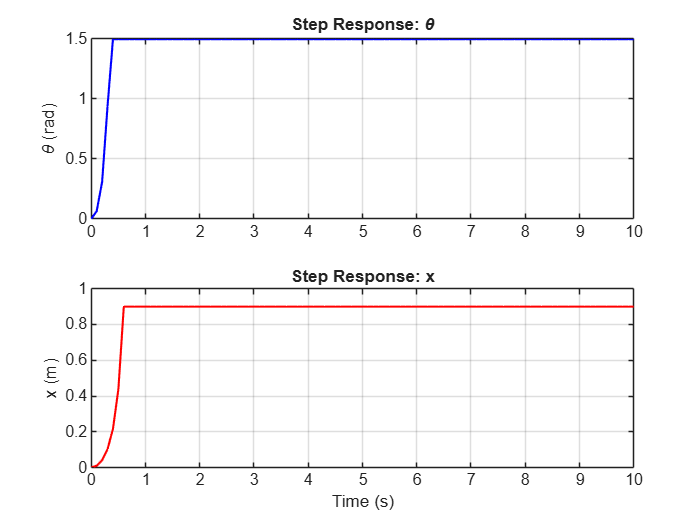

[y,tOut] = step(sys,10);
x_step = min(y(:,1),x_max); 
theta_step = min(y(:,2),phi_max); 

% Plot the step response for x and theta in a subplot
figure;
subplot(2,1,1);
plot(tOut, theta_step, 'b', 'LineWidth', 1.2); hold on;
ylabel('\theta (rad)');
title('Step Response: \theta');
grid on;

subplot(2,1,2);
plot(tOut, x_step, 'r', 'LineWidth', 1.2); hold on;
xlabel('Time (s)');
ylabel('x (m)');
title('Step Response: x');
grid on;

H = tf(sys)


H =
 
  From input "F" to output...
          1.927 s^2 + 5.134e-15 s - 116.6
   x:  --------------------------------------
       s^4 + 0.1927 s^3 - 81.58 s^2 - 11.66 s
 
                   11.88 s + 1.073e-16
   \theta:  ----------------------------------
            s^3 + 0.1927 s^2 - 81.58 s - 11.66
 
Continuous-time transfer function.


% Kloppen de coefficiënten in transferfunctie: 
(m_opt*l_opt)/(I_opt*(M_opt+m_opt) + M_opt*m_opt*l_opt^2)

ans = 11.8809

(I_opt + m_opt*l_opt^2)*b_opt/(I_opt*(M_opt+m_opt) + M_opt*m_opt*l_opt^2)

ans = 0.1927

-(M_opt+m_opt)*(m_opt*gn*l_opt)/(I_opt*(M_opt+m_opt) + M_opt*m_opt*l_opt^2)

ans = -81.5826

-(m_opt*gn*l_opt*b_opt)/(I_opt*(M_opt+m_opt) + M_opt*m_opt*l_opt^2)

ans = -11.6559

eig(An)

ans =          0
   -0.1429
   -9.0577
    9.0078


syms s
H_s = Cn * (s*eye(size(An,1)) - An)^(-1) * Bn

$$H\_s = \begin{array}{l} \left(\begin{array}{c} -\frac{138849940237860704\,\left(17592186044416\,s^{2}-1435216419833585\right)}{\sigma_{1}}-\frac{51533237033549851052281289392510}{\sigma_{1}}\\ \frac{5804577509930278458606869934741}{2\,\left(-1267650600228229401496703205376\,s^{3}-244282332805564296466219925504\,s^{2}+103418242136936812012087342530560\,s+14775551043222106116644543126371\right)}-\frac{6688340088528935\,\left(36028797018963968\,s+6942921481980997\right)}{16\,\left(-1267650600228229401496703205376\,s^{3}-244282332805564296466219925504\,s^{2}+103418242136936812012087342530560\,s+14775551043222106116644543126371\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-1267650600228229401496703205376\,s^{4}-244282332805564296466219925504\,s^{3}+103418242136936812012087342530560\,s^{2}+14775551043222106116644543126371\,s \end{array}$$

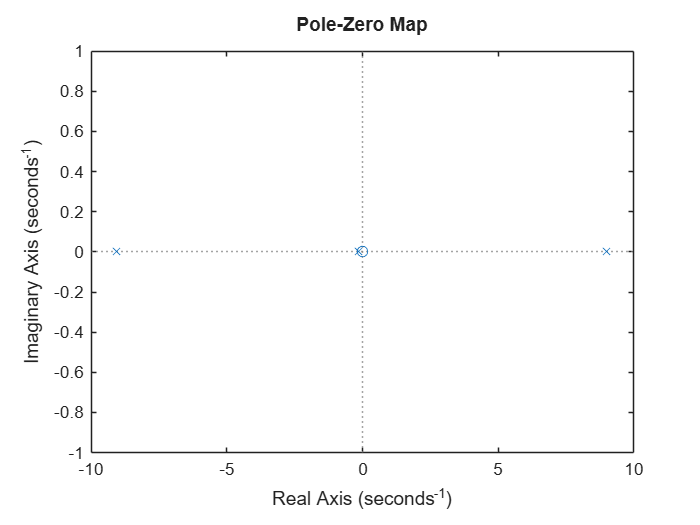

figure;
grid on;
pzmap(H(2,1))

pole(H(1,1))

ans =          0
    9.0078
   -9.0577
   -0.1429


pole(H(2,1))

ans =     9.0078
   -9.0577
   -0.1429


T_sample = 0.05;
sysd = c2d(sys, T_sample); Hd = tf(sysd)


Hd =
 
  From input "F" to output...
       0.002412 z^3 - 0.002789 z^2 - 0.002764 z + 0.002404
   x:  ---------------------------------------------------
         z^4 - 4.198 z^3 + 6.384 z^2 - 4.177 z + 0.9904
 
            0.01506 z^2 - 4.868e-05 z - 0.01501
   \theta:  -----------------------------------
            z^3 - 3.198 z^2 + 3.187 z - 0.9904
 
Sample time: 0.05 seconds
Discrete-time transfer function.


rank(ctrb(sysd))

ans = 4

rank(obsv(sysd)) 

ans = 4

p2 = pole(sysd(2))

p2 =     1.5689
    0.9929
    0.6358
    1.0000


z2 = zero(sysd(2))

z2 =    -0.9968
    1.0000
    1.0000


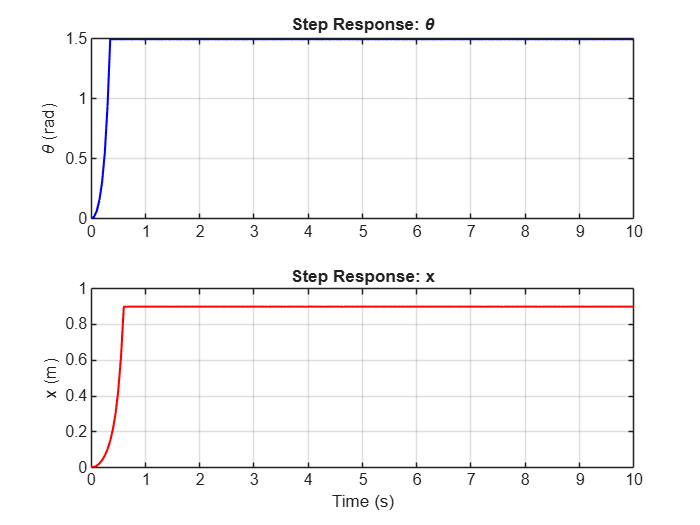

[yd,tOutd] = step(sysd,10);
xd_step = min(yd(:,1),x_max); 
thetad_step = min(yd(:,2),phi_max); 

% Plot the step response for x and theta in a subplot
figure;
subplot(2,1,1);
plot(tOutd, thetad_step, 'b', 'LineWidth', 1.2); hold on;
ylabel('\theta (rad)');
title('Step Response: \theta');
grid on;

subplot(2,1,2);
plot(tOutd, xd_step, 'r', 'LineWidth', 1.2); hold on;
xlabel('Time (s)');
ylabel('x (m)');
title('Step Response: x');
grid on;

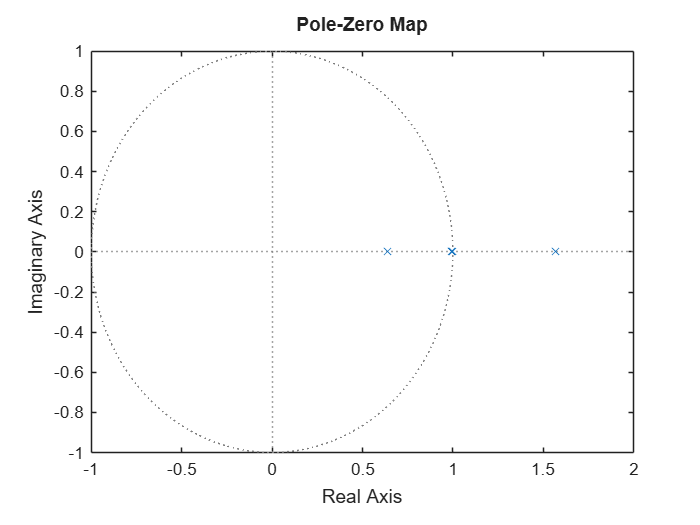


figure;
pzmap(sysd)

% 1. Data inladen
states_data = readmatrix('pendulum_states.csv')

states_data =          0         0    0.0100         0
    0.0023    0.0924    0.0223    0.4962
    0.0093    0.1871    0.0608    1.0655
    0.0211    0.2874    0.1314    1.7927
    0.0382    0.3955    0.2443    2.7714
    0.0608    0.5088    0.4142    4.0868
    0.0889    0.6111    0.6591    5.7646
    0.1210    0.6629    0.9955    7.7319
    0.1534    0.6067    1.4359    9.9290
    0.1791    0.3970    1.4960         0
    0.2007    0.4653    1.4960         0
    0.2256    0.5332    1.4960         0
    0.2540    0.6006    1.4960         0
    0.2857    0.6675    1.4960         0
    0.3207    0.7339    1.4960         0


inputs_data = readmatrix('pendulum_inputs.csv')

inputs_data =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


% Tijdstappen definiëren (T = 0.05s in je Python code)
T = 0.05;
t_sim = 0:T:(length(states_data)-1)*T;

% 2. Extractie van de gesimuleerde variabelen (Python)
x_sim = states_data(:, 1);     % Cart position
theta_sim = states_data(:, 3); % Pendulum angle

% % 3. Theoretische respons berekenen (MATLAB model)
% % We simuleren de respons op een stap van 1 Newton
% opt = stepDataOptions('StepAmplitude', 1);
% [y_theory, t_theory] = step(sysd, t_sim(end), opt)

u_sim = ones(size(t_sim)) * 1; 
x0 = [0; 0; 0.01; 0]; 

% 4. Simuleer met lsim
[y_theory, t_theory] = lsim(sysd, u_sim, t_sim, x0)

y_theory = 1.0e+76 *

         0    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000


t_theory =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500
    0.5000
    0.5500
    0.6000
    0.6500
    0.7000


x_theory = y_theory(:, 1);
theta_theory = y_theory(:, 2);


% De limieten definiëren
rail_max = 0.9;
rail_min = -0.95;
phi_max = pi/2.1;

% De theoretische data filteren (clamping)
theta_theory_clamped = theta_theory;
theta_theory_clamped(theta_theory > phi_max) = phi_max;
theta_theory_clamped(theta_theory < -phi_max) = -phi_max;

x_theory_clamped = x_theory;
x_theory_clamped(x_theory > rail_max) = rail_max;
x_theory_clamped(x_theory < rail_min) = rail_min;

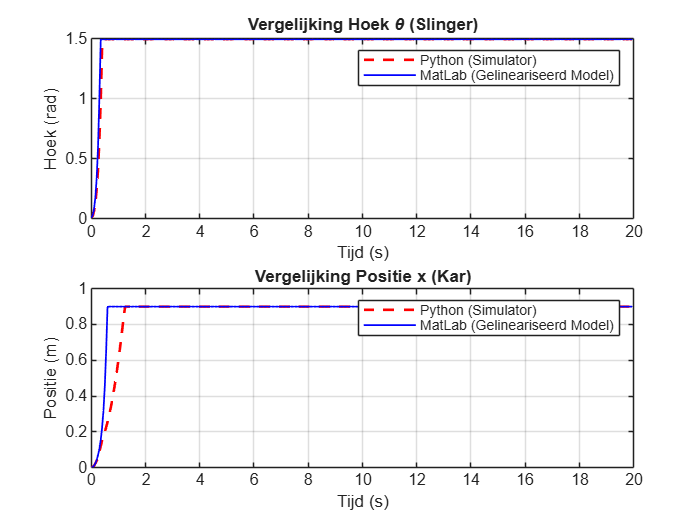

% 4. Visualisatie / Vergelijking
figure;

subplot(2,1,1);
plot(t_sim, theta_sim, 'r--', 'LineWidth', 1.5); hold on;
plot(t_theory, theta_theory_clamped, 'b', 'LineWidth', 1);
title('Vergelijking Hoek \theta (Slinger)');
xlabel('Tijd (s)'); ylabel('Hoek (rad)');
legend('Python (Simulator)', 'MatLab (Gelineariseerd Model)');
grid on;

subplot(2,1,2);
plot(t_sim, x_sim, 'r--', 'LineWidth', 1.5); hold on;
plot(t_theory, x_theory_clamped, 'b', 'LineWidth', 1);
title('Vergelijking Positie x (Kar)');
xlabel('Tijd (s)'); ylabel('Positie (m)');
legend('Python (Simulator)', 'MatLab (Gelineariseerd Model)');
grid on;

% Slechte x doordat theta niet meer klein blijft. Sin(theta) /= theta ->
% Model "denkt" dus dat de zwaartekracht veel harder aan de slinger trekt dan in de werkelijkheid het geval is


function mse = theta_mse(l,t,theta_fun,theta_sim,g, phi_max)
    theta_model = theta_fun(g,l,t);
    theta_model = min(theta_model,phi_max);
    mse = mean((theta_sim - theta_model').^2);
end

function mse = x_mse(p, t, x_fun, x_sim, x_max, F)
    Mplusm = p(1);b = p(2);
    x_model = x_fun(t, Mplusm, b, F);
    x_model = min(x_model,x_max);
    mse = mean((x_sim - x_model').^2);
end

function var_error = massacentrum_mse(m, x_kar, theta, l, M_total)
    M = M_total - m;
    if m < 0 || M < 0
        var_error = 1e10;
        return;
    end
    x_pend = x_kar - l * sin(theta);
    x_com = (m * x_pend + M * x_kar) / M_total;
    var_error = mean((x_com - mean(x_com)).^2);
end